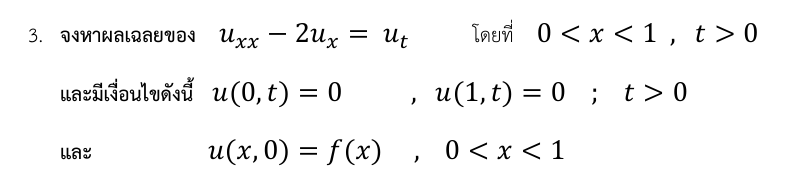

clearvars;clf;
% ตั้งค่าช่วงของ x และ t
x = linspace(-10, 10, 200); 
t = linspace(0, 10, 100);    
[X, T] = meshgrid(x, t);   
%initial condition
f = @(x) sin(x) - 1;   
g = @(x) cos(x);       

%d'Alembert's solution
F_xt = 0.5 * (f(X - T) + f(X + T));  
G_xt = 0.5 * (g(X - T) + g(X + T)) .* T; 
forcing_term = X + cos(T);
U = F_xt + G_xt + forcing_term;

**Plot graph**

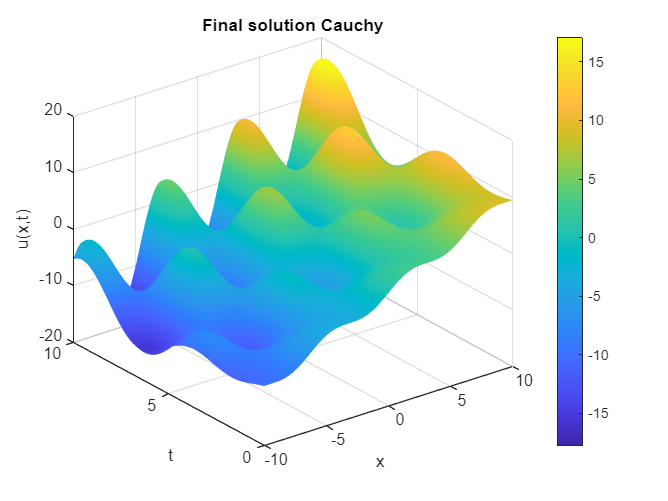

figure;
surf(X, T, U);
xlabel('x');
ylabel('t');
zlabel('u(x,t)');
title('Final solution Cauchy');
shading interp;
colorbar;